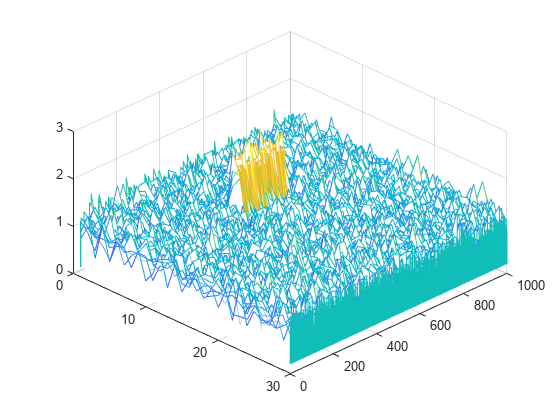

S = ones(30, 1000);
S(10:11, 400:600) = 2;
S = S + randn(30,1000) * 0.20;
S(S < 0) = 0;
figure
waterfall(S')

view([45 45])

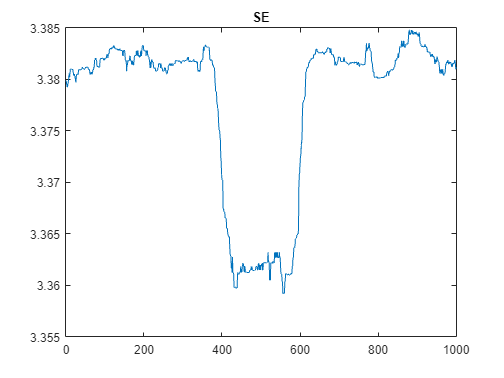


gmm = SEGMM(51);
gmm.detect(S)

figure
plot(gmm.H)
title("SE")

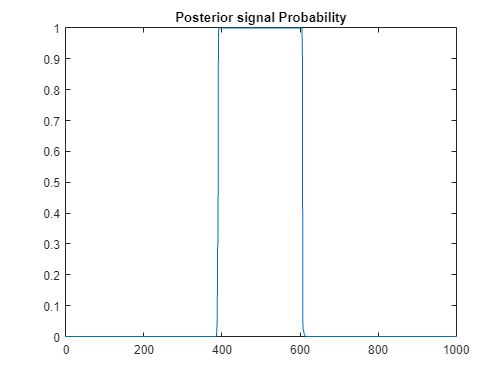


figure
plot(gmm.probs)
title("Posterior signal Probability")

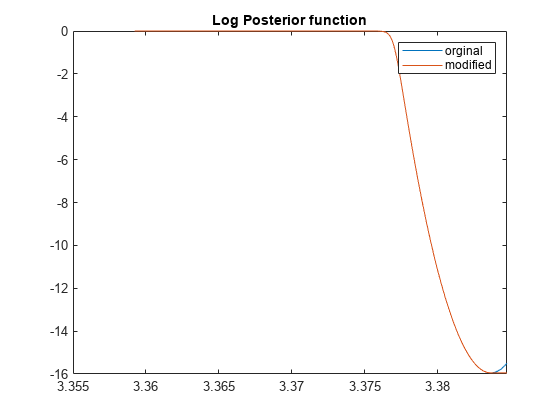


figure
plot(gmm.x, log(gmm.f))
title("Log Posterior function")
hold on
plot(gmm.x, log(gmm.fmod))
hold off
legend("orginal", "modified")

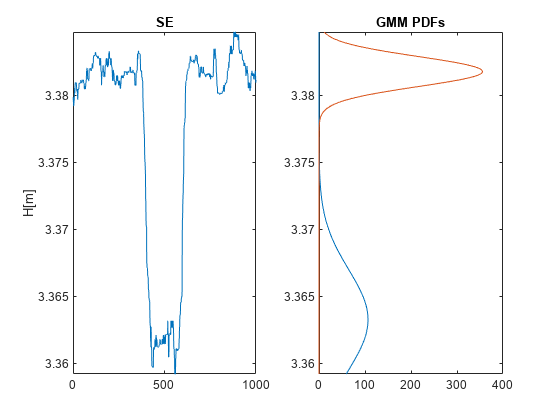



figure
subplot(121)
plot(gmm.H);
ylim([gmm.Hmin, gmm.Hmax])
title("SE")
ylabel("H[m]")
subplot(122)
plot(gmm.pdf, gmm.x)
ylim([gmm.Hmin, gmm.Hmax])
title("GMM PDFs")


gmm

gmm =   SEGMM with properties:

         MaxGMMIter: 200
    PosteriorThresh: 0.5000
                  M: 51
                  H: [3.3799 3.3796 3.3794 3.3792 3.3794 3.3796 3.3799 3.3802 3.3806 3.3802 3.3806 3.3810 3.3810 3.3810 3.3810 3.3810 3.3810 3.3810 3.3807 3.3805 3.3803 3.3805 3.3803 3.3802 3.3799 3.3797 3.3802 3.3805 3.3805 3.3805 3.3805 3.3805 … ]
              probs: [1.8849e-05 4.2598e-05 7.4798e-05 1.3476e-04 7.4798e-05 4.2598e-05 1.8849e-05 8.8629e-06 3.5433e-06 8.8629e-06 3.5433e-06 1.5803e-06 1.4858e-06 1.5803e-06 1.4858e-06 1.5803e-06 1.4858e-06 1.5803e-06 2.5112e-06 4.1453e-06 … ]
               mu_n: 3.3818
               mu_s: 3.3633
            sigma_n: 0.0011
            sigma_s: 0.0037
          converged: 1
             n_iter: 13
                 LL: 4.5922e+03
                mon: 0
               fmin: 1.1871e-07
               fmax: 1
                 Ht: 3.3770
             contam: 3.4953e-05
    